# ***Procesado basado en Machine Learining***

***Pietro Ruzzante CA13028II***

clear all
close all
clc

**DATASET BALANCEADO**

dataFolder = "./CC_1";
imds = imageDatastore(dataFolder, ...
    IncludeSubfolders=true, ...
    LabelSource="foldernames");

% figure
tiledlayout("flow");
perm = randperm(500,20);
for i = 1:20
    nexttile
    imshow(imds.Files{perm(i)});
end

classNames = categories(imds.Labels);
labelCount = countEachLabel(imds)

labelCount = 2×2 table
     Label     Count
    _______    _____

    Healthy     566 
    Sick        566 


Ntotal = length(imds.Files);

img = readimage(imds,1);
inputSize = [size(img) 1]

inputSize =    256   256     1


TrainPercent = 85/100;
numTrainFiles = round((Ntotal/2)*TrainPercent);
[imdsTrain,imdsTest] = splitEachLabel(imds,TrainPercent,"randomize");

La red aumenta en complejidad, comenzando con filtros más amplios y luego. Los filtros son desde el inicio de tamaño pequeño porque, para esta tarea específica (la detección del cáncer de mama), no es necesario buscar patrones grandes en la imagen, sino detalles pequeños y específicos en áreas reducidas 

Eliminamos la última capa convolucional, simplifico la red y quitamos las capas de maxPoolingLayer --> la precisión aumenta, pero todavía se mantiene en el 70%.

Si eliminamos la capa densa (dense layer), la precisión mejora notablemente desde las primeras iteraciones.

La precisión de validación sigue siendo baja incluso aumentando el dropout --> es necesario introducir data augmentation.

layers = [
    imageInputLayer([256 256 1])

    convolution2dLayer(3,4,'Padding',"same")
    batchNormalizationLayer
    reluLayer

    convolution2dLayer(3,16,'Padding',"same")
    batchNormalizationLayer
    reluLayer

    dropoutLayer(0.3)

    fullyConnectedLayer(2)
    softmaxLayer
    ];

nm = 10;
mbs = round(Ntotal*TrainPercent/nm);
options = trainingOptions("sgdm", ...
    InitialLearnRate=0.001, ...
    MaxEpochs=20, ...
    Shuffle="every-epoch", ...
    ValidationData=imdsValidation, ...
    MiniBatchSize=mbs,...
    ValidationFrequency=nm, ...
    Plots="training-progress", ...
    Metrics="accuracy", ...
    OutputNetwork="best-validation", ...
    Verbose=false);

net1 = trainnet(imdsTrain,layers,"crossentropy",options);

scores = predict(net1,imdsValidation);
YValidation = scores2label(scores,classNames);
TValidation = imdsValidation.Labels;
accuracy = mean(YValidation == TValidation)

CM = confusionmat(TValidation, YValidation);
TN = CM(1,1);
FP = CM(1,2);
FN = CM(2,1);
TP = CM(2,2);

precision = TP/(TP+FP);
recall = TP/(TP+FN);
f1 = 2*precision*recall/(precision+recall);

Es importante no aplicar reflexión sobre el eje X porque todas las imágenes tienen los nódulos a la izquierda.

Nota: utilizando randreplicatefiles, el código me generaba algunos errores que no pude resolver. Por lo tanto, implementé un código que realiza la misma función, combinando la replicación de archivos y la data augmentation:

augmenter = imageDataAugmenter( ...
    'RandXTranslation', [-10, 10], ...
    'RandYTranslation', [-10, 10], ... 
    'RandScale', [0.8, 1.2]);          

inputSize = [256 256 1]; 

outputDir = fullfile(tempdir, 'augmented_images');
if ~exist(outputDir, 'dir')
    mkdir(outputDir);
end

originalFiles = imdsTrain.Files;

augmentedFiles = {};
for i = 1:numel(originalFiles)
    img = imread(originalFiles{i});
    
    for j = 1:2
        augmentedImg = augment(augmenter, img); 
        
        augmentedFileName = fullfile(outputDir, ['aug_' num2str(i) '_' num2str(j) '.png']);
        imwrite(augmentedImg, augmentedFileName);
        augmentedFiles{end + 1} = augmentedFileName;
    end
end

allFiles = [originalFiles; augmentedFiles'];
allLabels = [imdsTrain.Labels; repmat(imdsTrain.Labels, 2, 1)];

newImds = imageDatastore(allFiles, 'Labels', allLabels);




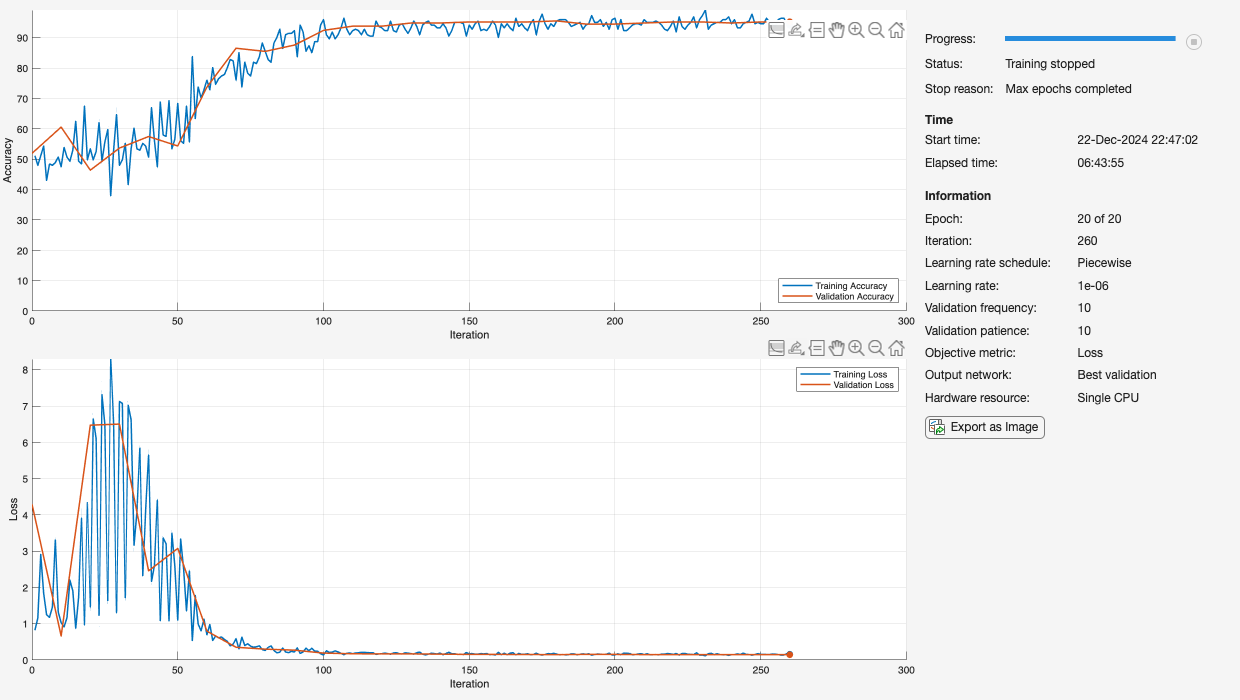

Fold 1/10
Fold 2/10
Fold 3/10
Fold 4/10
Fold 5/10
Fold 6/10
Fold 7/10


layers2 = [
    imageInputLayer([256 256 1])

    convolution2dLayer(3,32,'Padding',"same")
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2, Stride=2)

    convolution2dLayer(3,64,'Padding',"same")
    batchNormalizationLayer
    reluLayer

    dropoutLayer(0.3)

    fullyConnectedLayer(2)
    softmaxLayer
    ];

nm = 10;
mbs = round(Ntotal*TrainPercent/nm);
options = trainingOptions("sgdm", ...
    InitialLearnRate=0.0001, ...
    LearnRateSchedule="piecewise", ...
    LearnRateDropFactor=0.1, ...
    LearnRateDropPeriod=7, ...
    L2Regularization=0.0001, ...
    MaxEpochs=20, ...
    Shuffle="every-epoch", ...
    ValidationPatience=10, ...
    ValidationData=imdsValidation, ...
    MiniBatchSize=mbs,...
    ValidationFrequency=nm, ...
    Plots="training-progress", ...
    Metrics="accuracy", ...
    OutputNetwork="best-validation", ...
    Verbose=false);

net2 = trainnet(newImds,layers2,"crossentropy",options);

scores2 = minibatchpredict(net2, imdsTest);
TValidation = imdsTest2.Labels;
YValidation2 = scores2label(scores2, classNames);
accuracy2 = mean(YValidation2 == TValidation);
disp("Accuracy dopo il secondo training: " + accuracy2);

Accuracy dopo il secondo training: 0.9




CM = confusionmat(TValidation, YValidation2);
TN = CM(1,1);
FP = CM(1,2);
FN = CM(2,1);
TP = CM(2,2);

precision = TP/(TP+FP);
recall = TP/(TP+FN);
f1 = 2*precision*recall/(precision+recall);

El modelo ahora es capaz de generalizar bien, con valores excelentes incluso en el conjunto de validación.

**DATASET DESBALANCEADO**

dataFolder2 = "./CC_2";
imds_unbalanced = imageDatastore(dataFolder2, ...
    IncludeSubfolders=true, ...
    LabelSource="foldernames");

labelCount = countEachLabel(imds_unbalanced)

labelCount = 2×2 table
     Label     Count
    _______    _____

    Healthy    1132 
    Sick        566 


augmenter = imageDataAugmenter( ...
    'RandXTranslation', [-10, 10], ...
    'RandYTranslation', [-10, 10], ... 
    'RandScale', [0.8, 1.2]);   

new_sick_count = 0; 
new_healthy_count = 0;

outputDir = fullfile(tempdir, 'augmented_balanced_images');
if ~exist(outputDir, 'dir')
    mkdir(outputDir);
else
    % Rimuovi i file esistenti nella directory
    delete(fullfile(outputDir, '*.png'));
end

originalFiles = imds_unbalanced.Files;
originalLabels = imds_unbalanced.Labels;

augmentedFiles = {};
augmentedLabels = {};

for i = 1:numel(originalFiles)
    if originalLabels(i) == "Sick" 
        new_sick_count = new_sick_count+1; 
        img = imread(originalFiles{i});
          augmentedFileName = fullfile(outputDir, ['aug_' num2str(i) '_' num2str(j) '.png']);

          if ~exist(augmentedFileName, 'file')
                augmentedImg = augment(augmenter, img); 
                imwrite(augmentedImg, augmentedFileName);
                augmentedFiles{end + 1} = augmentedFileName;
                augmentedLabels{end + 1} = char(originalLabels(i));
            end

    end
end

allFiles = [originalFiles; augmentedFiles'];
allLabels = [originalLabels; augmentedLabels'];

newImds_balanced = imageDatastore(allFiles, 'Labels', allLabels);

labelCount_balanced = countEachLabel(newImds_balanced)

labelCount_balanced = 2×2 table
     Label     Count
    _______    _____

    Healthy    1132 
    Sick       1132 



[imdsTrain2,imdsValidation2] = splitEachLabel(newImds_balanced,TrainPercent,"randomize");

layers3 = [
    imageInputLayer([256 256 1])

    convolution2dLayer(3,32,'Padding',"same")
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2, Stride=2)

    convolution2dLayer(3,64,'Padding',"same")
    batchNormalizationLayer
    reluLayer

    dropoutLayer(0.5)

    fullyConnectedLayer(2)
    softmaxLayer
    ];

nm = 10;
mbs = round(2*Ntotal*TrainPercent/nm);
options = trainingOptions("sgdm", ...
    InitialLearnRate=0.0001, ...
    LearnRateSchedule="piecewise", ...
    LearnRateDropFactor=0.1, ...
    LearnRateDropPeriod=7, ...
    L2Regularization=0.001, ...
    MaxEpochs=20, ...
    Shuffle="every-epoch", ...
    ValidationPatience=10, ...
    ValidationData=imdsValidation2, ...
    MiniBatchSize=mbs,...
    ValidationFrequency=nm, ...
    Plots="training-progress", ...
    Metrics="accuracy", ...
    OutputNetwork="best-validation", ...
    Verbose=false);

net3 = trainnet(imdsTrain2,layers3,"crossentropy",options);


scores3 = minibatchpredict(net3, imdsTest2);
TValidation = imdsTest2.Labels;
YValidation2 = scores2label(scores2, classNames);
accuracy2 = mean(YValidation2 == TValidation);
disp("Accuracy dopo il secondo training: " + accuracy2);


CM = confusionmat(TValidation, YValidation2);
TN = CM(1,1);
FP = CM(1,2);
FN = CM(2,1);
TP = CM(2,2);

precision2 = TP/(TP+FP);
recall2 = TP/(TP+FN);
f12 = 2*precision*recall/(precision+recall);

Aunque usemos el dataset debalanceado, con la data augmentation se pueden obtener los mismos resultados.